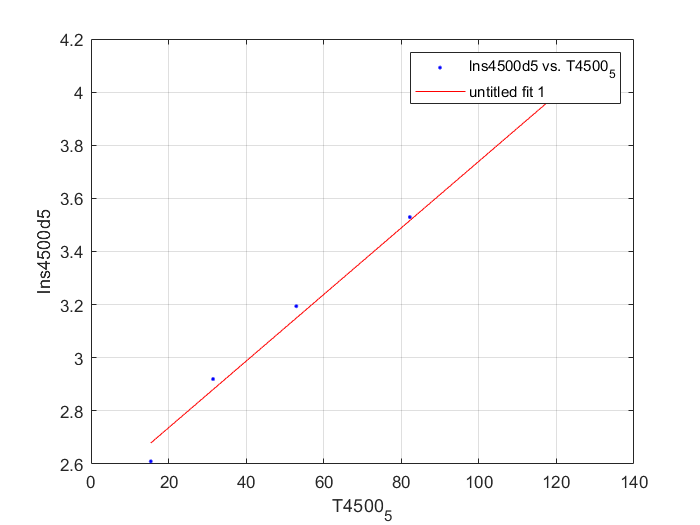

%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( T4500_5, lns4500d5 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns4500d5 vs. T4500_5', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T4500_5
ylabel lns4500d5
grid on



%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01254  (0.01057, 0.01451)
  %     p2 =       2.486  (2.34, 2.632)

%Goodness of fit:
 % SSE: 0.00925
  %R-square: 0.9927
  %Adjusted R-square: 0.9903
  %RMSE: 0.05553